%%Load the simulate data
out=load('SimulatedData\fermi-dirac-simulation-9.csv');
kz=out(:,1);
n1d=out(:,2);
addpath('Library');
% mask=1:1:1000;
% kz=kz(mask);
% n1d=n1d(mask);

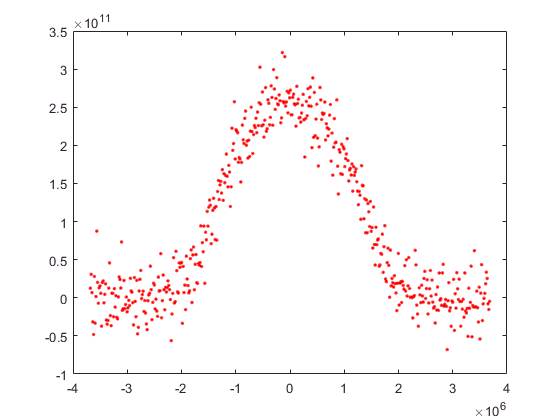

plot(kz,n1d,'r.')

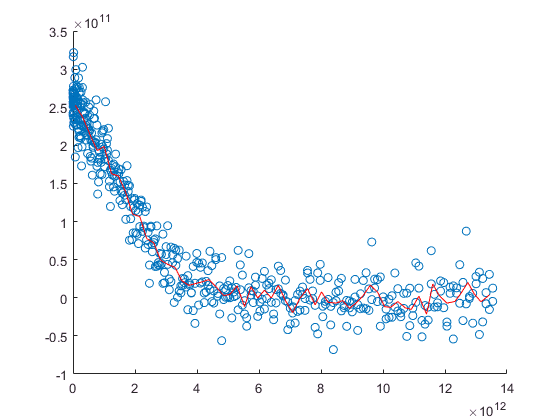

%%First do the binning
Nbin=60;
SM=2;
ksq=kz.^2;
ksqmin=min(ksq);ksqmax=max(ksq);
ksqBinGrid=linspace(ksqmin,ksqmax,Nbin+1);
[ ksqBin,n1dkBin,~,~ ] = BinGrid( ksq,n1d,ksqBinGrid,0 );
% ksqBin=ksq;n1dkBin=n1d;
fk=-4*pi*FiniteD( ksqBin,n1dkBin,SM );
% fk=-4*pi*PolyD( ksqBin,n1dkBin,10 );
kzBin=sqrt(ksqBin);
scatter(ksq,n1d)
hold on
plot(ksqBin,n1dkBin,'r-')
hold off

FDfun=@(P,k) P(1)*1./(exp(P(2)*(k.^2/P(3)-1))+1);
P0=[1,5,(max(kzBin)/2)^2];
P=nlinfit(kzBin,fk,FDfun,P0);

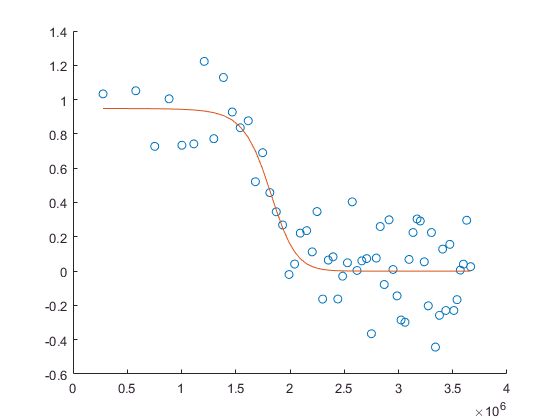

ffit=FDfun(P,kzBin);

scatter(kzBin,fk);
hold on
plot(kzBin,ffit);
hold off


disp(P(1));

    0.9488



disp(1/P(2));

    0.1346

